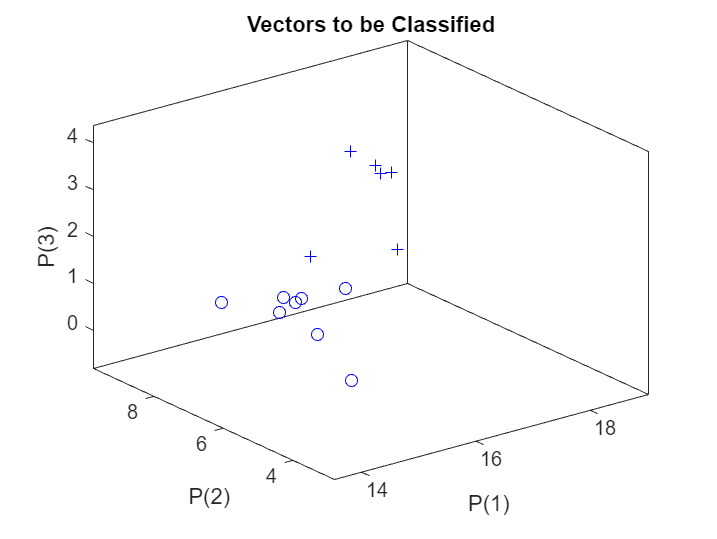

%国家类型的自适应分类(变量除以标准差)
clear
P=[17.5503 17.0400 17.7500 17.4615 16.2190 16.6406 16.8181 14.7990 15.8197 15.6865 16.1747 15.4868 15.3981 14.7990 
8.0905 8.0905 8.0905 8.0905 7.9025 6.0965 7.8780 8.1313 8.0251 7.4530 8.0905 7.5838 6.3580 4.3885 
2.5590 3.2125 2.5237 2.7684 1.3036 1.9228 0.4305 0.7010 0.5218 0.6517 0.3638 0.4653 0.4380 0.3300]; 
                                            %输入变量
T=[1 1 1 1 1 1 0 0 0 0 0 0 0 0];            %目标输出
plotpv(P,T);                                %绘制训练样品分类立体图
net=newp(minmax(P),1);                      %创建一个感知器网络
handle=plotpc(net.iw{1},net.b{1});          %在训练前的分类图中绘制分界面
net.adaptParam.passes=2;                    %设定自适应循环次数
for a=1:25                                  %指定迭代次数为25次
    [net,Y,e]=adapt(net,P,T);               %调用自适应函数训练网络
    handle=plotpc(net.iw{1},net.b{1},handle);drawnow;%添加分类界面
end;

Y                                           %输出训练样品的分类结果

Y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_test=[17.4615 17.3506 15.5756 15.0875 
8.0905 7.9189 8.0006 6.7666 
2.2418 1.5130 0.6129 0.3369];               %输入判样品信号
y=sim(net,P_test);y                         %待判样品的仿真分类结果

y =      1     1     1     1


w=net.iw{1,1}                               %输出权数向量

w =    62.4587   12.0638  157.1369


b=net.b{1}                                  %输出阈值

b = -4